clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)

imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files=dir(label_directory)

labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


imgs = zeros(512,512,3,18,'uint8');
labels = zeros(512,512,3,18,'uint8');
for i=3:20
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)

ans =    512   512     3    18


size(labels)

ans =    512   512     3    18


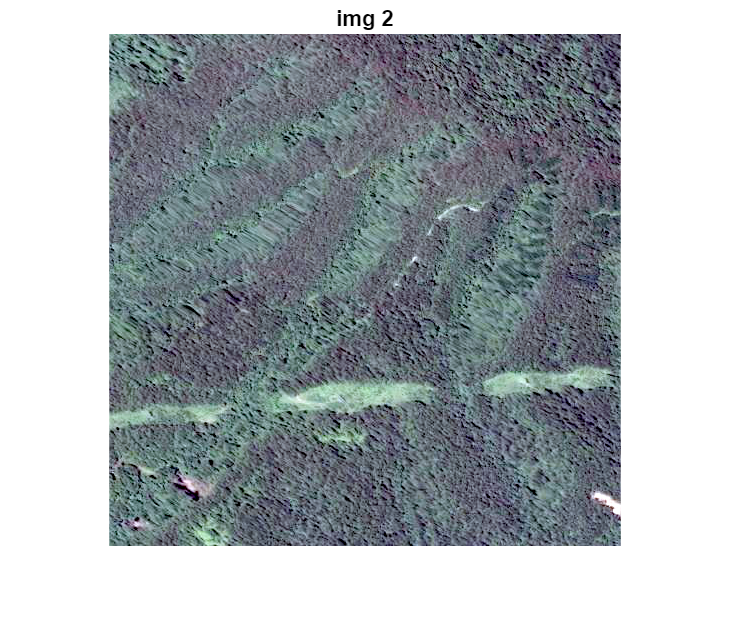


img_2 = imgs(:,:,:,2);
label_2 = labels(:,:,:,2);
figure;
imshow(img_2);
title('img 2');

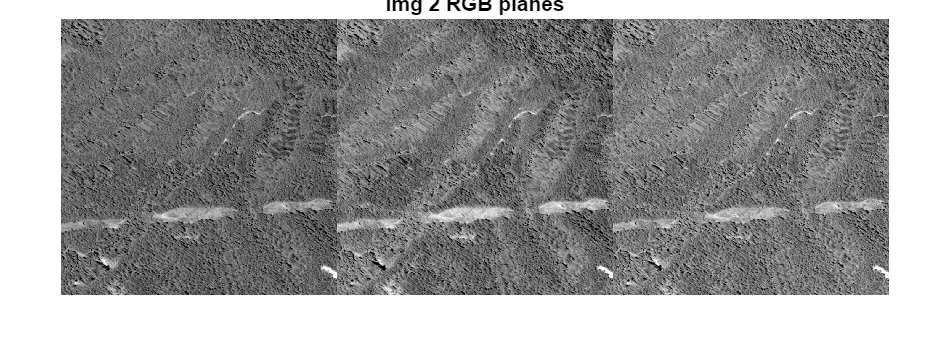

figure;
montage([img_2(:,:,1), img_2(:,:,2), img_2(:,:,3)]);
title('img 2 RGB planes');

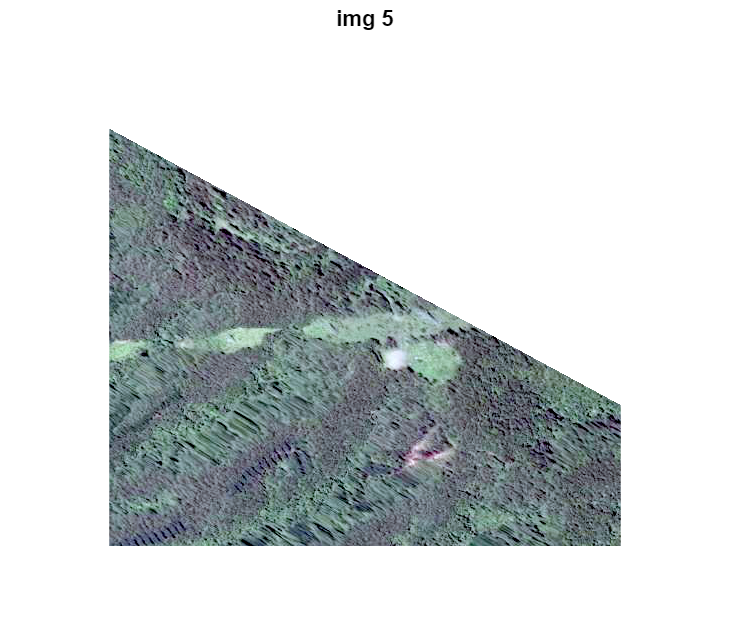

img_5 = imgs(:,:,:,5);
figure;
imshow(img_5);
title('img 5');

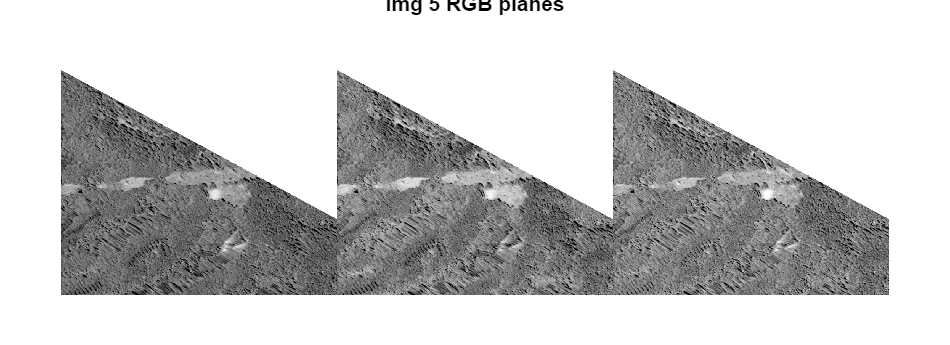

montage([img_5(:,:,1), img_5(:,:,2), img_5(:,:,3)]);
title('img 5 RGB planes');

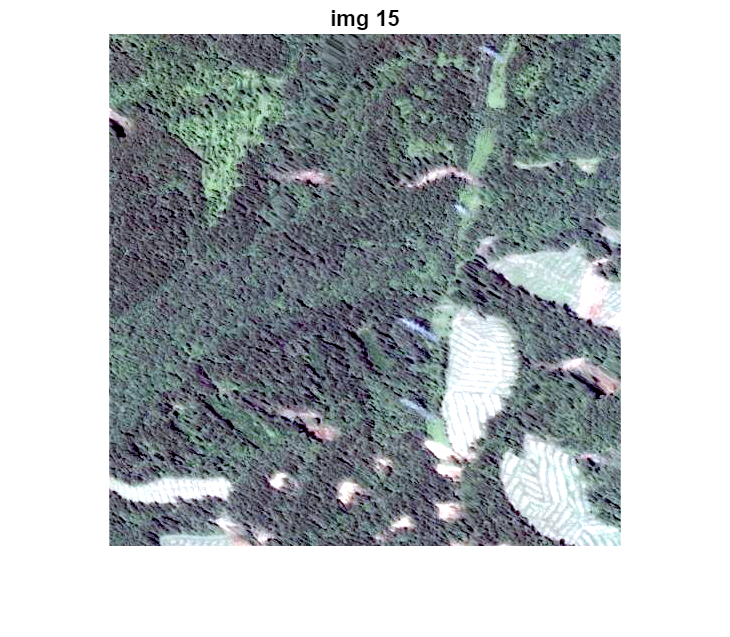

img_15 = imgs(:,:,:,15);
figure;
imshow(img_15);
title('img 15');

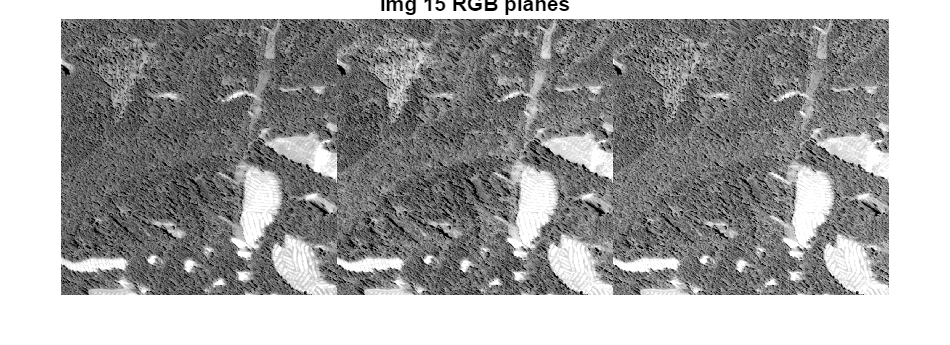

montage([img_15(:,:,1), img_15(:,:,2), img_15(:,:,3)]);
title('img 15 RGB planes');

figure;
imshow(img_2);
title('Image 2');
figure;
imshow(label_2);
title('Image 2')

% Extract colour channels
R_2 = img_2(:,:,1); % Red CH
G_2 = img_2(:,:,2); % Green CH
B_2 = img_2(:,:,3); % Blue CH

figure;
subplot(1,3,1);
imshow(R_2);
title('R plane');
subplot(1,3,2);
imshow(R_2);
title('G plane');
subplot(1,3,3);
imshow(R_2);
title('B plane');

Ehance contrast - DEFINITELY USEDUL

% Extract colour channels
R_2 = img_2(:,:,1); % Red CH
G_2 = img_2(:,:,2); % Green CH
B_2 = img_2(:,:,3); % Blue CH

% Enhane contrast of green plane before removal
G_2_eq = histeq(G_2);
img_2_green_enhance = img_2;
img_2_green_enhance(:,:,2) = G_2_eq;
figure;
imshow(img_2_green_enhance);
title('Img 2 w/ Enhanced G Plane');

% Enhane contrast of red plane before removal
R_2_eq = histeq(R_2);
img_2_red_enhance = img_2;
img_2_red_enhance(:,:,1) = R_2_eq;
figure;
imshow(img_2_red_enhance);
title('Img 2 w/ Enhanced R Plane');

% Enhane contrast of green plane before removal
B_2_eq = histeq(B_2);
img_2_blue_enhance = img_2;
img_2_blue_enhance(:,:,3) = B_2_eq;
figure;
imshow(img_2_blue_enhance);
title('Img 2 w/ Enhanced B Plane');

figure;
subplot(1,3,1);
imshow(img_2_red_enhance);
title('Img 2 w/ Enhanced R Plane');
subplot(1,3,2);
imshow(img_2_green_enhance);
title('Img 2 w/ Enhanced G Plane');
subplot(1,3,3);
imshow(img_2_blue_enhance);
title('Img 2 w/ Enhanced B Plane');

% Extract colour channels
R_2 = img_2(:,:,1); % Red CH
G_2 = img_2(:,:,2); % Green CH
B_2 = img_2(:,:,3); % Blue CH

% Enhance rgb planes to enhance contrast
R_2_eq = histeq(R_2);
G_2_eq = histeq(G_2);
B_2_eq = histeq(B_2);
img_2_eq = cat(3,R_2_eq,G_2_eq,B_2_eq);
figure;
imshow(img_2_eq);
title('Img 2 contrast enhanced (equalised)');

figure;
subplot(1,3,1);
imshow(img_2);
title('Img 2');
subplot(1,3,2);
imshow(img_2_eq);
title('Img 2 equalised');
subplot(1,3,3);
imshow(label_2);
title('Label 2');

Make more blocky - DEFINITELY USEDUL

% Extract colour channels
R_2 = img_2(:,:,1); % Red CH
G_2 = img_2(:,:,2); % Green CH
B_2 = img_2(:,:,3); % Blue CH

% Apply quant to reduce #CH of unique green values
levels = 1; % Controll blockiness (higher = smoother)
quant = 256 / levels;
G_2_quantized = round(G_2 / quant) * quant;
img_2_green_quant = img_2;
img_2_green_quant(:,:,2) = G_2_quantized; % Replace green channel w/ quantised version
figure;
imshow(img_2_green_quant);
title('Img 2 w/ Quant G Plane')
figure;
imshow(img_2);
title('Img 2 Orig')

Enhance contrast & quantise G plane

% Extract colour channels
R_2 = img_2(:,:,1); % Red CH
G_2 = img_2(:,:,2); % Green CH
B_2 = img_2(:,:,3); % Blue CH

% Enhance contrast
G_2_eq = histeq(G_2);
img_2_enhance_g = img_2;
img_2_enhance_g(:,:,2) = G_2_eq;

% Apply quant to reduce #CH of unique green values
levels = 1; % Controll blockiness (higher = smoother)
quant = 256 / levels;
G_2_quantized = round(G_2_eq / quant) * quant;
img_2_green_quant = img_2;
img_2_green_quant(:,:,2) = G_2_quantized; % Replace green channel w/ quantised version
figure;
imshow(img_2);
title('Img 2 Orig');
figure;
imshow(img_2_enhance_g);
title('Img 2 G Plane Enhanced Contrast')
figure;
imshow(img_2_green_quant);
title('Img 2 G Plane Quantised');
figure;
imshow(255-img_2_green_quant);
title('Img 2 Inverted');

Another potential - or not

img = 255-img_2_green_quant;
[m, n, ~] = size(img);
img_reshaped = double(reshape(img, m*n, 3)); % Reshape for clustering

% Apply K-Means clustering (k=3 or 4 works well)
k = 3; % Adjust based on image
[idx, C] = kmeans(img_reshaped, k, 'Replicates', 5);

% Find the cluster with the highest green value
[~, green_cluster] = max(C(:,2)); % Cluster with max green intensity

% Create mask of green pixels
green_mask = (idx == green_cluster);
img_2_no_green = img;
img_2_no_green(repmat(reshape(green_mask, m, n), [1,1,3])) = 0; % Set to black
figure;
imshow(img_2_no_green);


Remove green

% Find indices where green channel is of high intensity
[row_g, col_g] = find(G_2_quantized > 150);

% Set those pixels within image to high
for i = 1:length(row_g)
    R_2(row_g(i), col_g(i)) = 0;
    G_2_quantized(row_g(i), col_g(i)) = 0;
    B_2(row_g(i), col_g(i)) = 0;
end

% Reconstruct image
img_2_no_green = cat(3,R_2,G_2,B_2);

figure;
imshow(img_2_no_green);
title('Green removed')

% % Define mask for dominant pixels
% green_mask = (G_2 > 1.2 * R_2) & (G_2 > 1.2 * B_2) & (G_2 > 50);
% 
% % Create output image and set to black
% img_2_no_green = img_2;
% img_2_no_green(repmat(green_mask, [1,1,3])) = 255;
% figure;
% imshow(img_2_no_green);
% title('Green removed')


img = img_2

% Convert to HSV
hsv_img = rgb2hsv(img);
H = hsv_img(:,:,1); % Hue
S = hsv_img(:,:,2); % Saturation
V = hsv_img(:,:,3); % Value

% Define a green mask in the HSV space
green_mask = (H > 0.8) & (H < 0.40) & (S > 0) & (V > 0.2); 

% Convert green pixels to black
img_2_no_green = img;
img_2_no_green(repmat(green_mask, [1,1,3])) = 0; % Set green pixels to [0,0,0] (black)

imshow(img_2_no_green);


img = img_2
G = img(:,:,2); % Extract Green channel

% Apply histogram equalization to green channel
G_eq = histeq(G);

% Replace green channel with equalized version
img_eq = img;
img_eq(:,:,2) = G_eq;

imshow(img_eq); % Display result



histogram(img_15)

img_5_dilated = zeros(512, 512, 3);
se_v1 = strel("square",1);
for i=1:3
    img_5_dilated(:,:,i) = imdilate(img_5(:,:,i),se_v1);
end
figure;
subplot(1,2,1)
imshow(img_5(:,:,1));
title('img 5 Orig R plane');
subplot(1,2,2)
imshow(img_5_dilated(:,:,1));
title('img 5 Dilated R plane');
figure;
subplot(1,2,1)
imshow(img_5(:,:,2));
title('img 5 Orig G plane');
subplot(1,2,2)
imshow(img_5_dilated(:,:,2));
title('img 5 Dilated G plane');
figure;
subplot(1,2,1)
imshow(img_5(:,:,3));
title('img 5 Orig B plane');
subplot(1,2,2)
imshow(img_5_dilated(:,:,3));
title('img 5 Dilated B plane');

% montage([label_5(:,:,1),label_5(:,:,2),label_5(:,:,3), ...
%     label_5_dilated(:,:,1),label_5_dilated(:,:,2),label_5_dilated(:,:,3)])
% 
% title('Orig label 5 vs Dilated');
% imshow(label_5);
% title('Label 5 Orig');
% figure;
% imshow(label_5_dilated);
% title('Label 5 Dialated');
% figure;
% montage([label_5, label_5_dilated]);
% title('Label 5 Orig Vs Dialated');

V1

clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)
labels_files=dir(label_directory)
imgs = zeros(512,512,3,18,'uint8');
labels = zeros(512,512,3,18,'uint8');
for i=3:20
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)
size(labels)

img_2 = imgs(:,:,:,2);
label_2 = labels(:,:,:,2);

% Extract colour channels
R_2 = img_2(:,:,1); % Red CH
G_2 = img_2(:,:,2); % Green CH
B_2 = img_2(:,:,3); % Blue CH

% Enhance contrast
G_2_eq = histeq(G_2);
img_2_enhance_g = img_2;
img_2_enhance_g(:,:,2) = G_2_eq;

% Apply quant to reduce #CH of unique green values
levels = 1; % Controll blockiness (higher = smoother)
quant = 256 / levels;
G_2_quantized = round(G_2_eq / quant) * quant;
img_2_green_quant = img_2;
img_2_green_quant(:,:,2) = G_2_quantized; % Replace green channel w/ quantised version

figure;
imshow(label_2);
title('Label 2');
figure;
imshow(img_2);
title('Orignal Img 2');
figure;
imshow(img_2_enhance_g);
title('Img 2 enahnced')
figure;
imshow(img_2_green_quant);
title('Img 2 w/ G Plane Equ & Quant');

figure;
histogram(img_2);
figure;
histogram(img_2_green_quant);

Makes LANDLSIDE WHITE THE BIGGEST WHITE SECTION SO COMBINATION OF EQ QUANT AND CANNY!

img_2_gray = rgb2gray(img_2_green_quant); % Convert to grayscale
img_2_edges = edge(img_2_gray,'Canny'); % Detect edges

% Create G plane mask
G_2 = img_2_green_quant(:,:,2); 
green_mask = (G_2 > 0.5 * img_2_green_quant(:,:,1)) & (G_2> 1.1 * img_2_green_quant(:,:,3)) & (G_2 > 200);

% Preserve edges whilst removing G plane
green_mask(img_2_edges) = 0; % Keep edges intact
img_2_no_green = img_2_green_quant;
img_2_no_green(repmat(green_mask, [1,1,3])) = 0; 

figure;
imshow(img_2_no_green);

figure;
imshow(img_2_edges);

% img = img_2
% 
% % Segment into superpixels
% numSuperpixels = 100; % Adjust for different levels of segmentation
% [L, N] = superpixels(img, numSuperpixels);
% 
% % Compute mean color of each superpixel
% mask = zeros(size(img,1), size(img,2), 'logical');
% for i = 1:N
%     % Get pixel indices in this superpixel
%     idx = find(L == i);
%     meanColor = mean(img(idx,:), 1);
% 
%     % If the superpixel is green-dominated, remove it
%     if meanColor(2) > 1.2 * meanColor(1) && meanColor(2) > 1.2 * meanColor(3)
%         mask(idx) = 1;
%     end
% end
% 
% % Apply mask to remove green areas
% img_2_no_green = img;
% img_2_no_green(repmat(mask, [1,1,3])) = 0;
% 
% imshow(img_2_no_green);

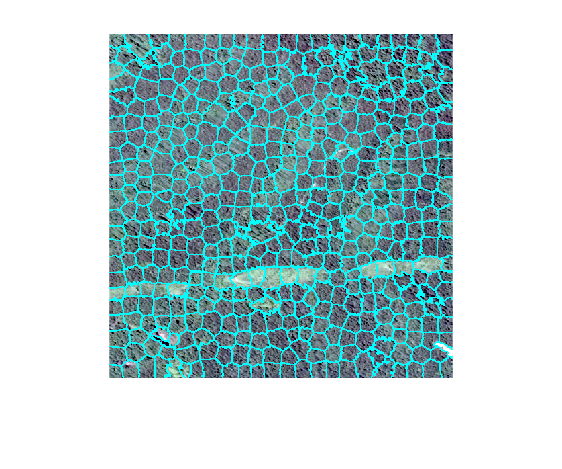

A = img_2;
% Calculate superpixels of the image.
[L,N] = superpixels(A,500);
%Display the superpixel boundaries overlaid on the original image.
figure
BW = boundarymask(L);
imshow(imoverlay(A,BW,'cyan'),'InitialMagnification',67)

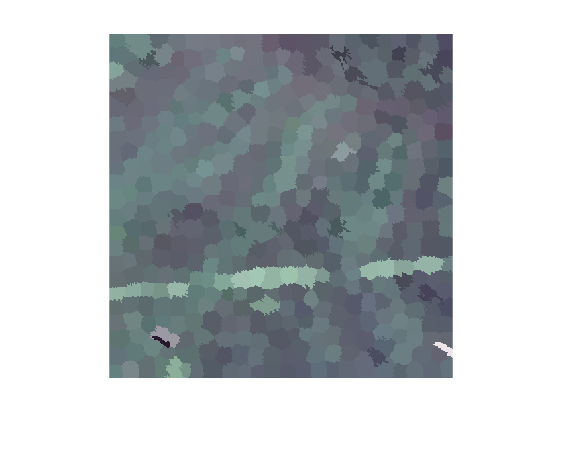

outputImage = zeros(size(A),'like',A);
idx = label2idx(L);
numRows = size(A,1);
numCols = size(A,2);
for labelVal = 1:N
    redIdx = idx{labelVal};
    greenIdx = idx{labelVal}+numRows*numCols;
    blueIdx = idx{labelVal}+2*numRows*numCols;
    outputImage(redIdx) = mean(A(redIdx));
    outputImage(greenIdx) = mean(A(greenIdx));
    outputImage(blueIdx) = mean(A(blueIdx));
end    

figure
imshow(outputImage,'InitialMagnification',67)

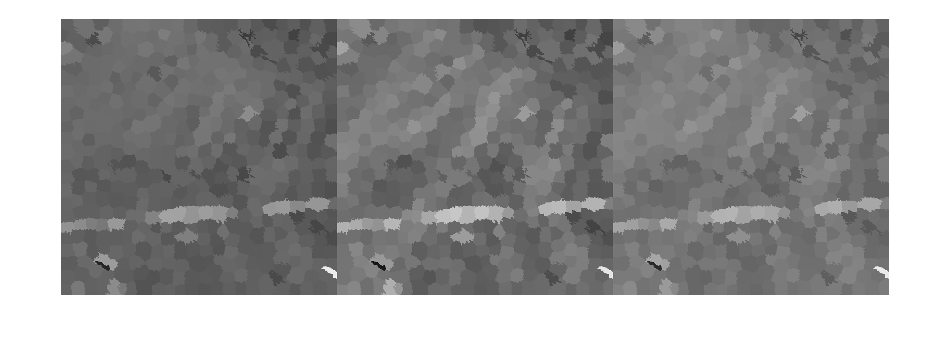


figure;
montage([outputImage(:,:,1),outputImage(:,:,2),outputImage(:,:,3)]);

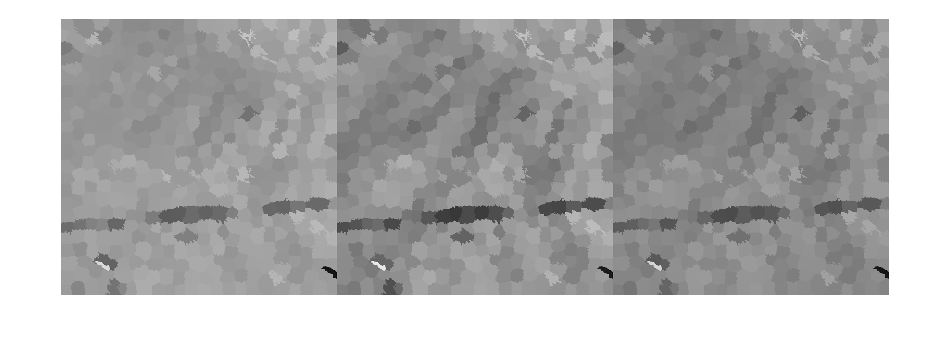

figure;
montage([255-outputImage(:,:,1),255-outputImage(:,:,2),255-outputImage(:,:,3)]);